% Experiment 5 - CNN 5 FOLD
% Author: Akshay.R 


close all;
clear variables;
existing_GUIs = findall(0);
if length(existing_GUIs) > 1
    delete(existing_GUIs);
end
clc;

## Read the image data from the relevant text files.

folder = "/Users/akshay/Desktop/ASS/CUB_200_2011_Subset20classes/";
imgFolder = folder + "images/";
imgTxtFolder = folder + "images.txt";

% Load in all images from the dataset folder into one datastore
allImageDS = imageDatastore(imgFolder, 'IncludeSubfolders', true, ...
                            'LabelSource','foldernames');

## Split dataset into five folds (=partitions) for fivefold cross-validation.

Split dataset into 5 x 20% - Note, splitEachLabel splits the datastore into N+1 new datastores, so by specifying 0.2 four times, we will end up with five 20% partitions.

[fold1DS, fold2DS, fold3DS, fold4DS, fold5DS] = ...
    splitEachLabel(allImageDS, 0.2, 0.2, 0.2, 0.2);

% Set target size for common width and height after cropping
targetSize = [224, 224];

% Number of folds is five in this experiment
numFolds = 5;

## Create a simple CNN

%% Create a simple CNN
layers = [
    imageInputLayer([224 224 3])    % This needs to match the image size chosen above
    
    convolution2dLayer(3, 8, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)
    
    convolution2dLayer(3, 16, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)
    
    convolution2dLayer(3, 32, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, 'Stride', 2)
    
    fullyConnectedLayer(20)
    softmaxLayer
    classificationLayer];

## Check if we have a GPU available and clear any old data from it

if (gpuDeviceCount() > 0)
    device = gpuDevice(1);
    reset(device);  % Clear previous values that might still be on the GPU
end

## Train the simple CNN model for each fold

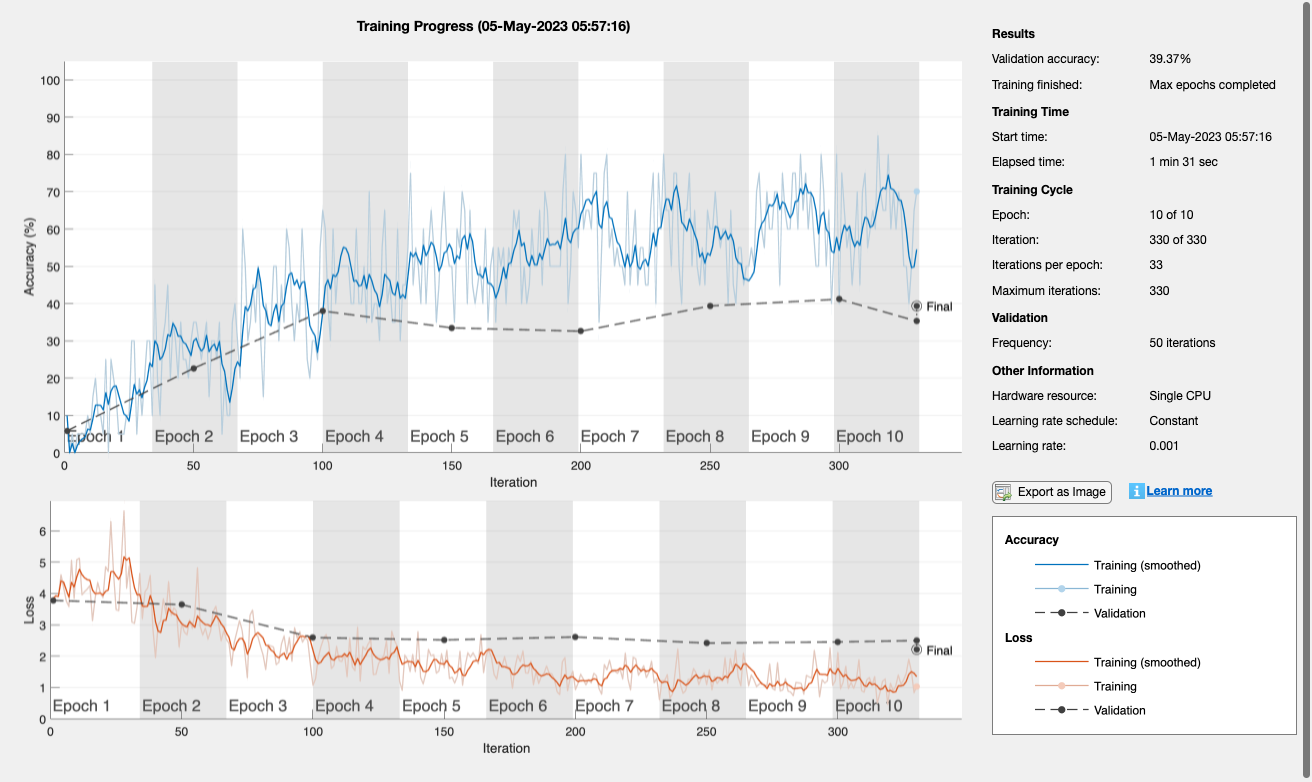

Accuracy for Run 1 is: 0.40444


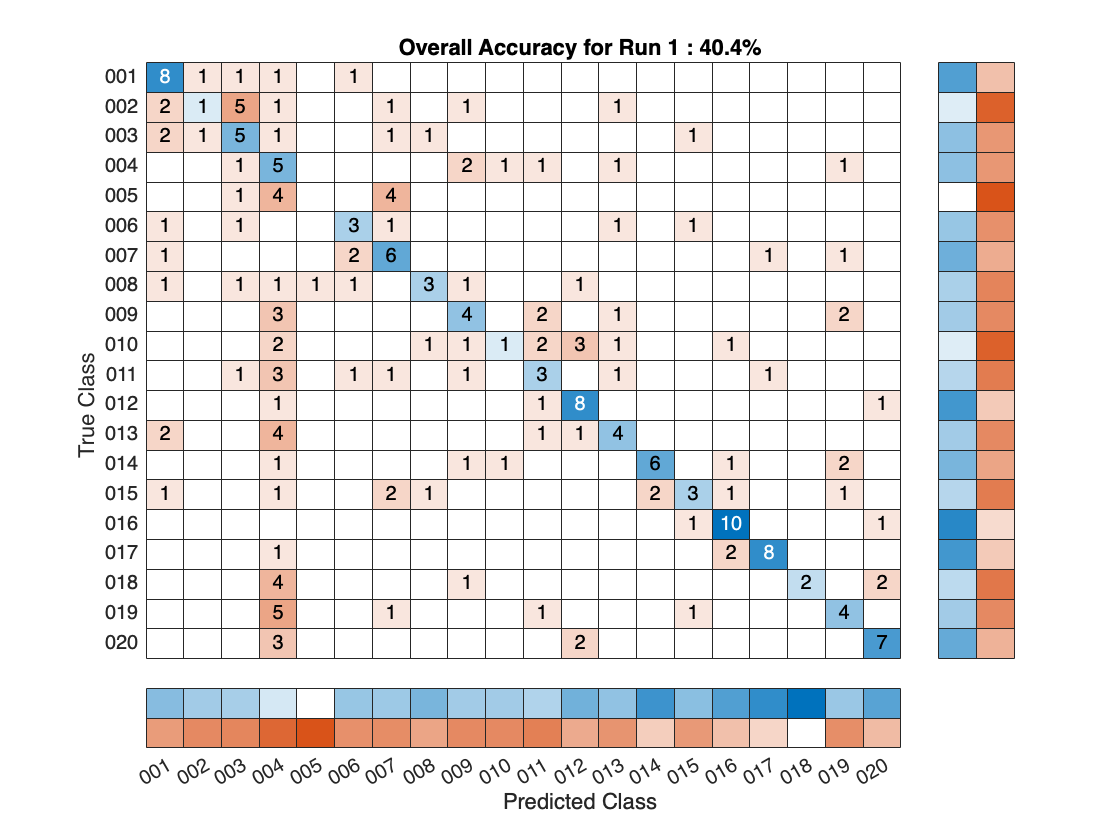

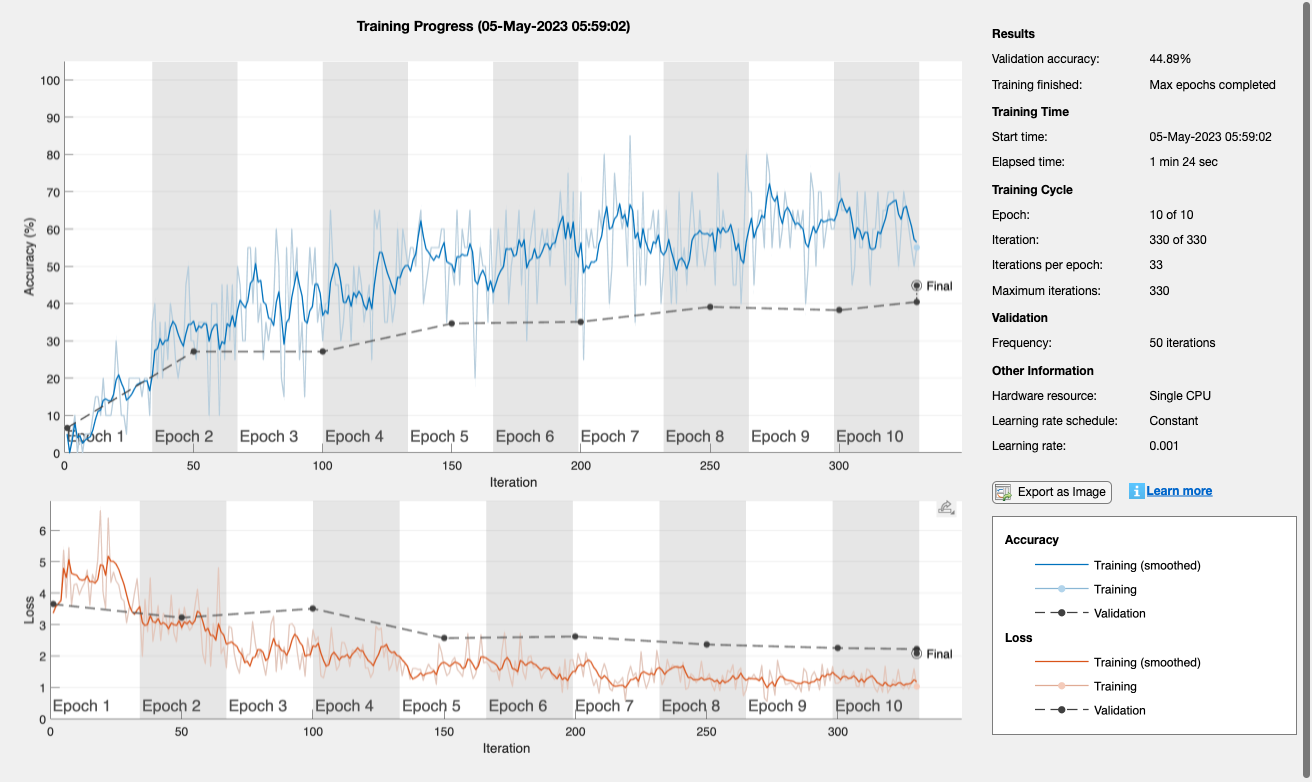

Accuracy for Run 2 is: 0.46222


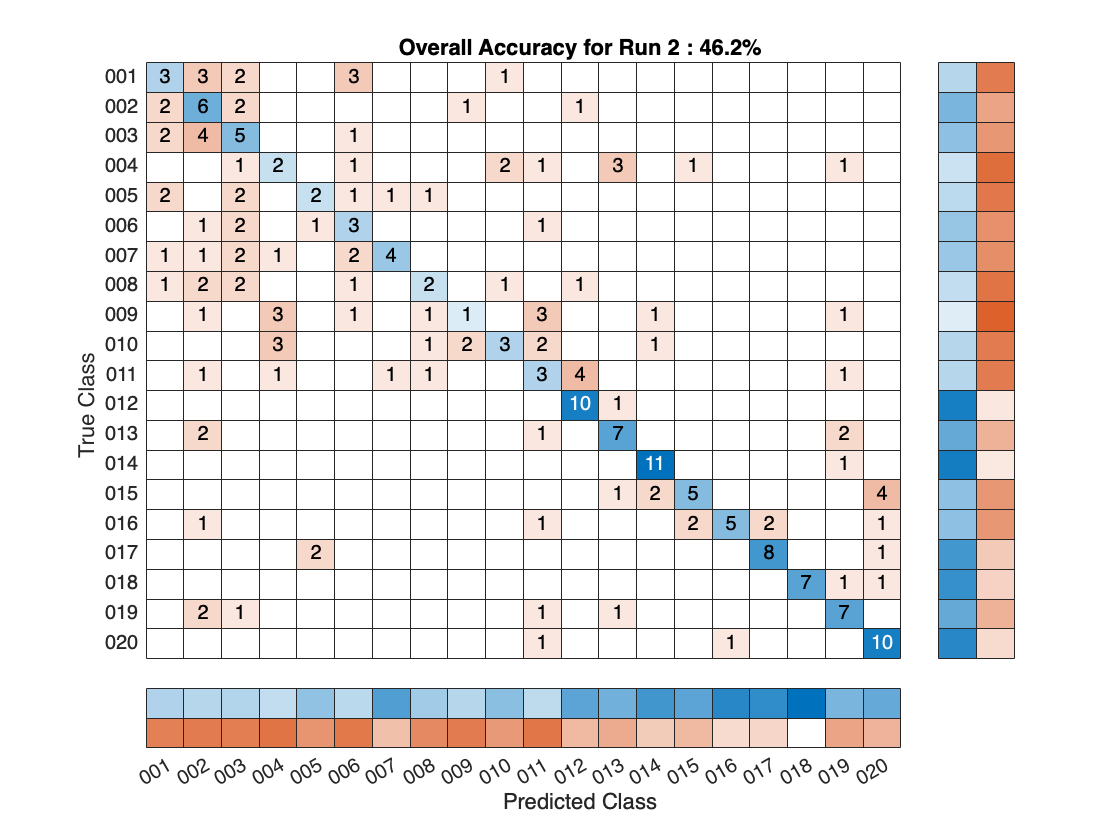

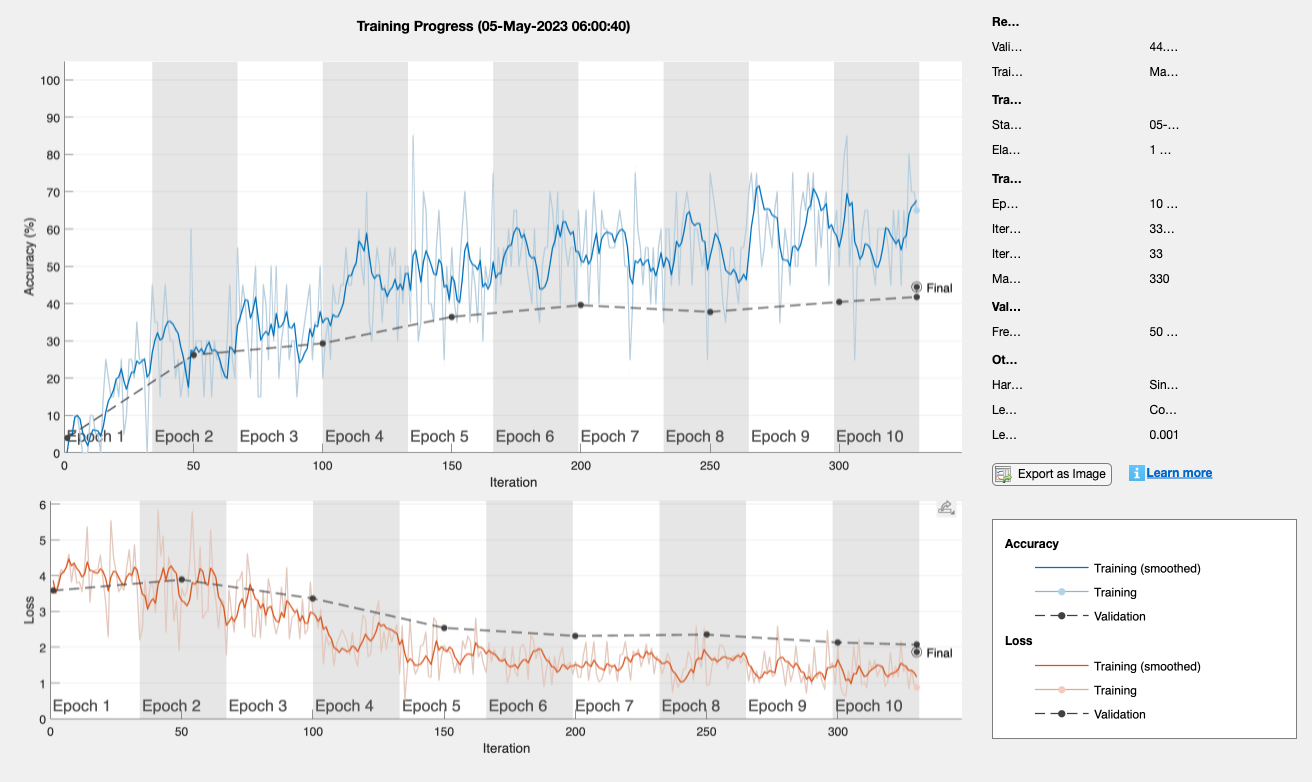

Accuracy for Run 3 is: 0.49321


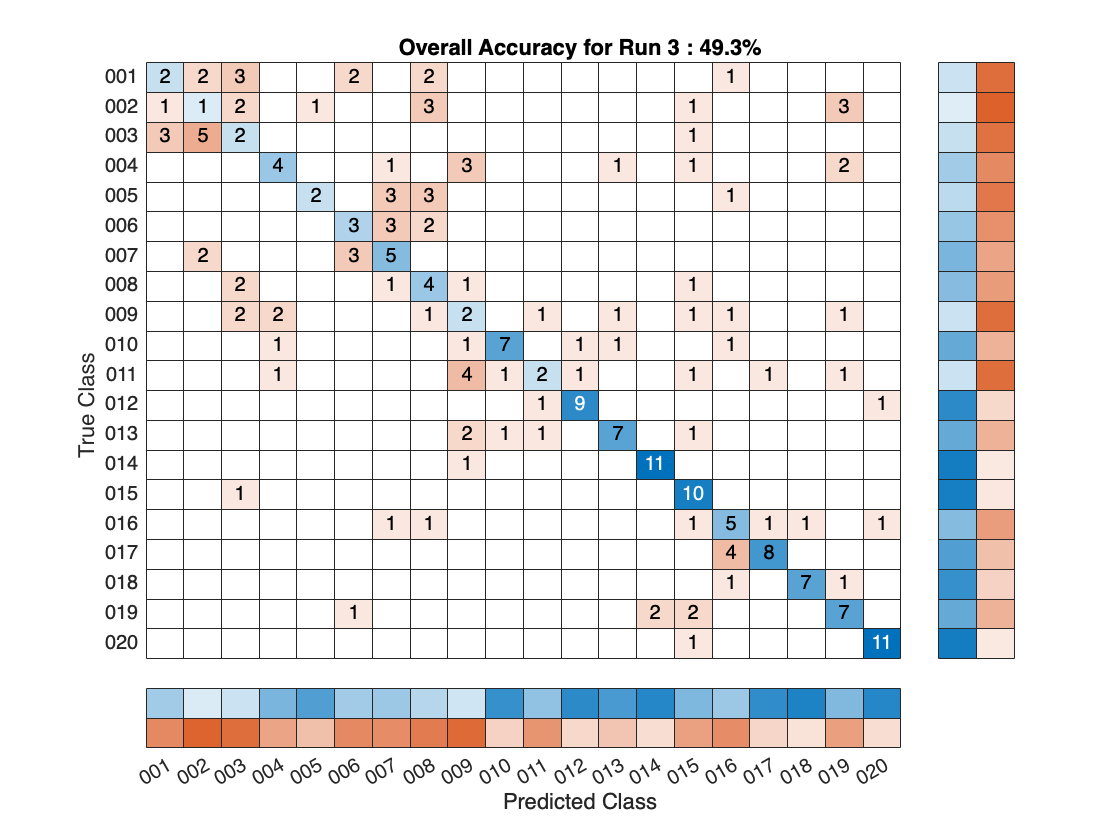

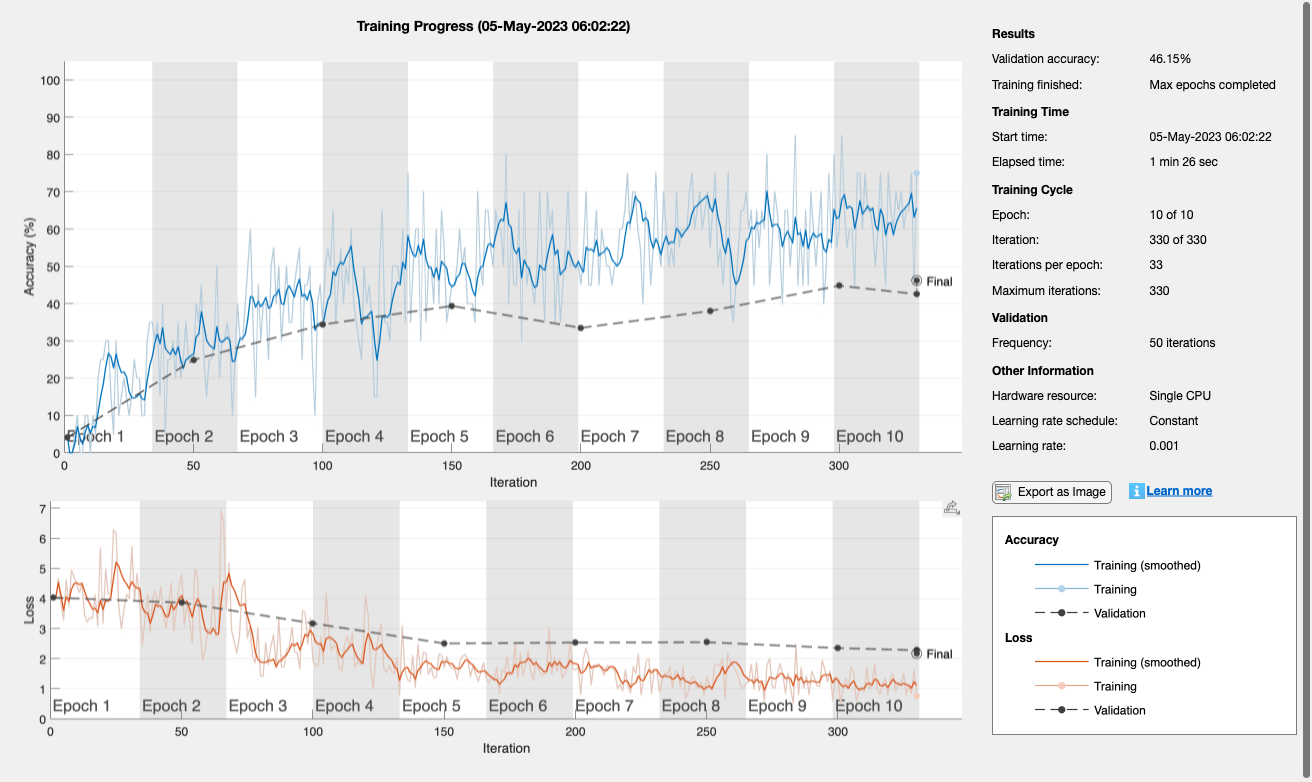

Accuracy for Run 4 is: 0.43498


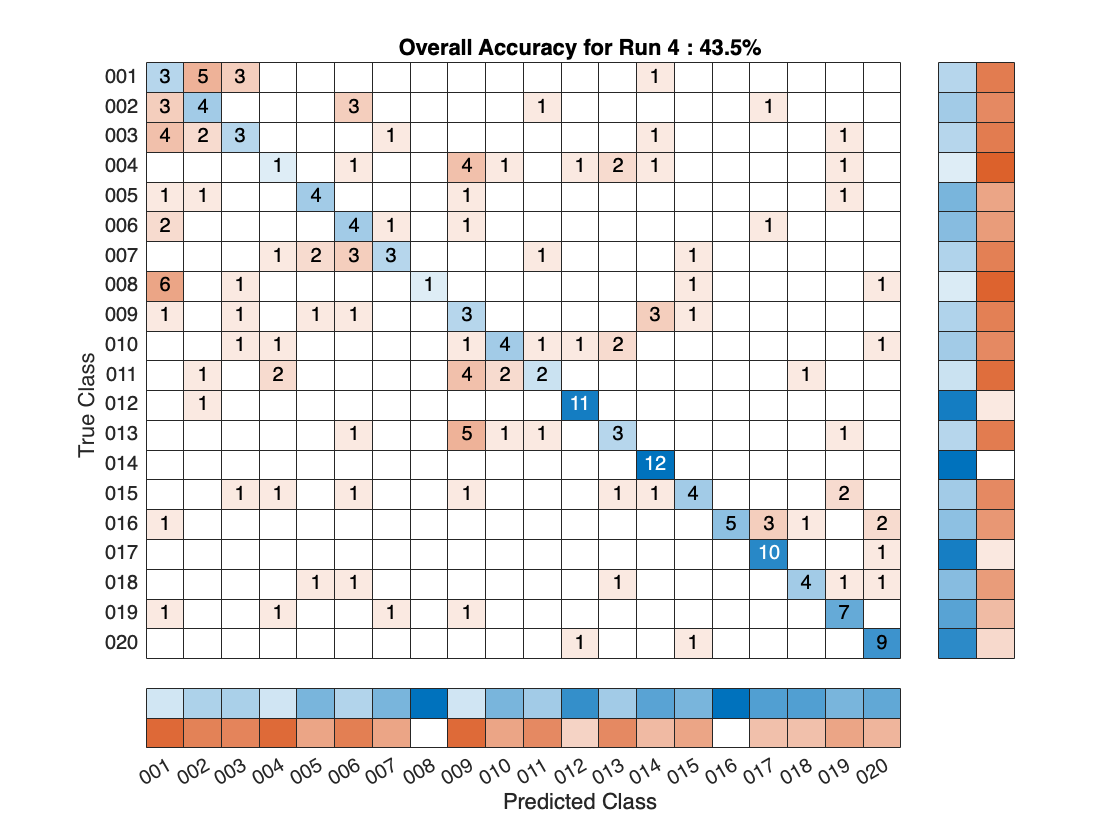

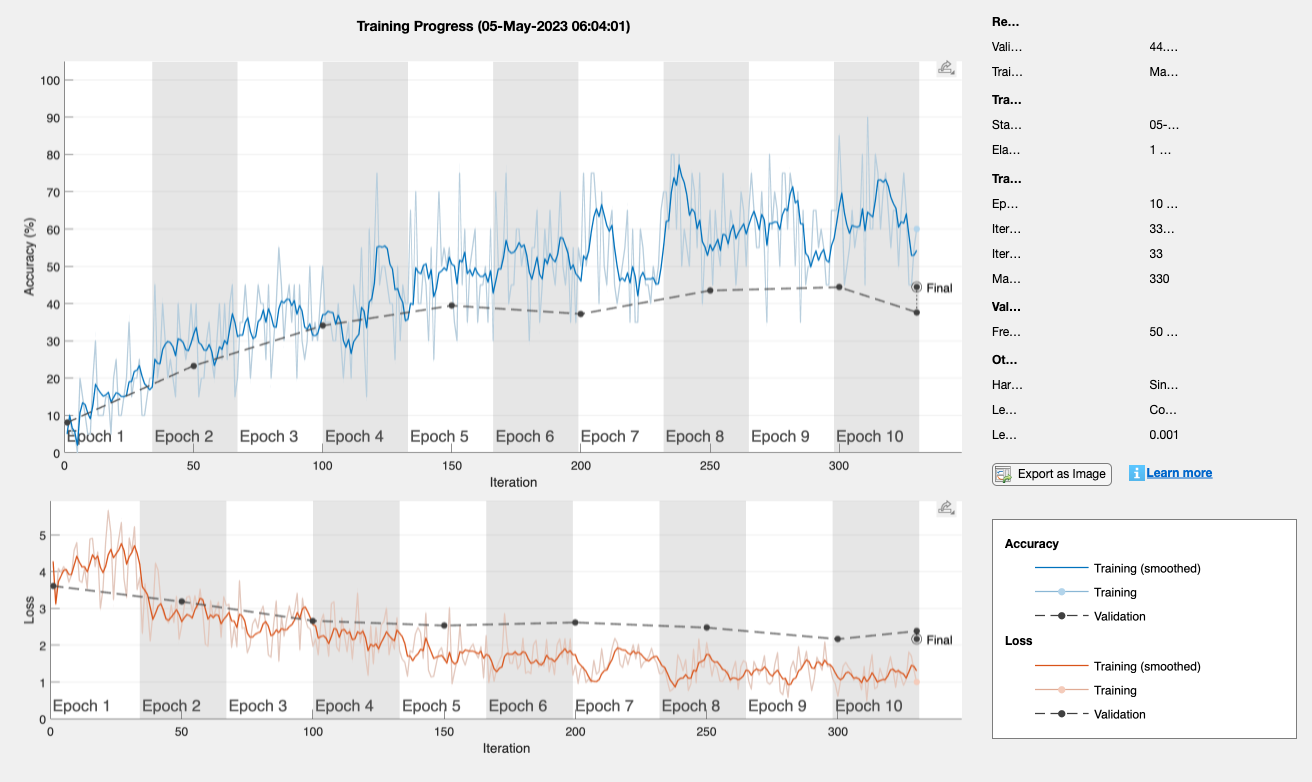

Accuracy for Run 5 is: 0.44796


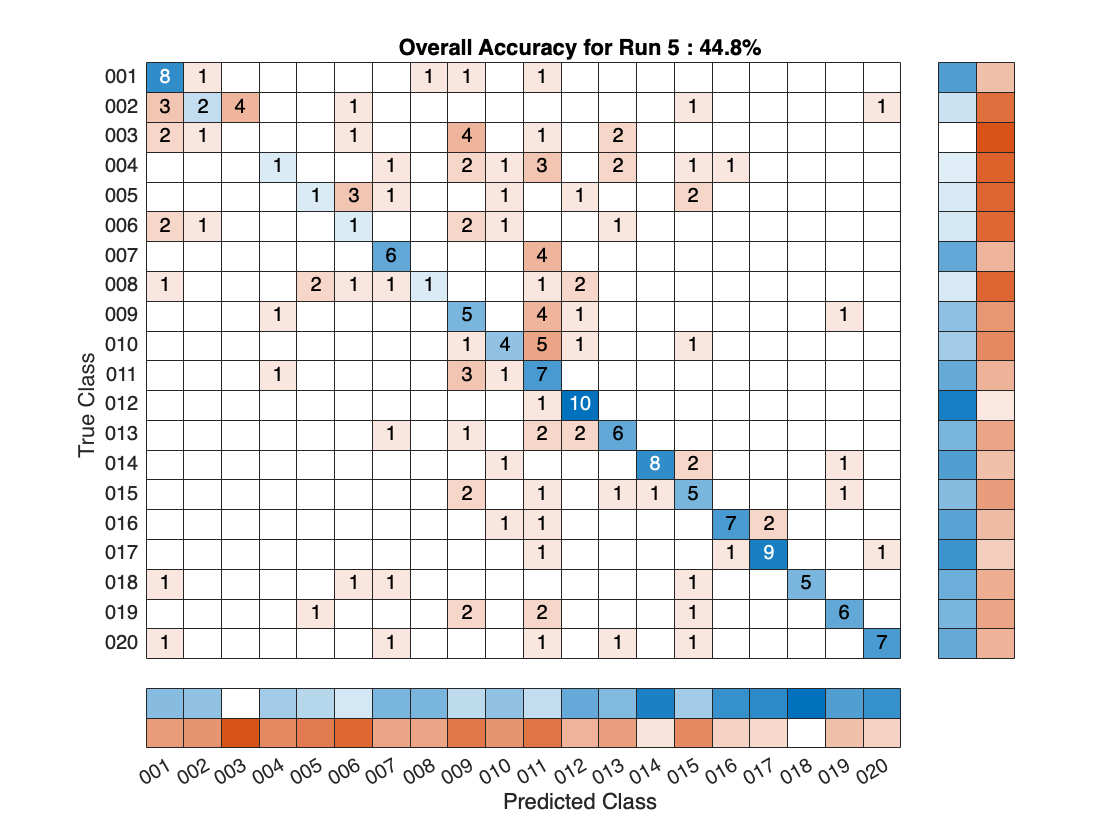

accuracy_overall = 0.0;
for i = 1:numFolds
    [augmentedTrainingImageDS, validationImageDS_Resized, testImageDS_Resized, trainingImageDS, ...
        validationImageDS, testImageDS] = ...
        getFoldsFor5FoldCrossVal(i, fold1DS, fold2DS, fold3DS, fold4DS, ...
                                 fold5DS, folder, imgTxtFolder, targetSize);


% Set the training options
    options = trainingOptions('sgdm', ...
        'InitialLearnRate', 0.001, ...
        'MiniBatchSize', 20, ...
        'MaxEpochs', 10, ...
        'Verbose', false, ...
        'Shuffle', 'every-epoch', ...
        'VerboseFrequency', 1, ...
        'ValidationData', validationImageDS_Resized, ...
        'Plots','training-progress');

    simpleCNN = trainNetwork(augmentedTrainingImageDS, layers, options);

    YPred = classify(simpleCNN, testImageDS_Resized);
    YTest = testImageDS.Labels;
    
    accuracy = sum(YPred == YTest)/numel(YTest); % Output on command line
    disp("Accuracy for Run "+ string(i)+" is: " + accuracy);

    % Show confusion matrix in figure
    [m, order] = confusionmat(YTest, YPred);
    figure(i);
    cm = confusionchart(m, order, ...
        'ColumnSummary','column-normalized', ...
        'RowSummary','row-normalized');
    title("Overall Accuracy for Run "+ string(i)+" : "+ ...
        string(round(accuracy*100, 1)) +"%");

    accuracy_overall = accuracy_overall+accuracy;
end


disp("Average accuracy of five folds is "+ string(accuracy_overall/numFolds))

Average accuracy of five folds is 0.44856
